% Load params

N_E = 100; % number of excitory neurons
N_I = 100; % number of inhibitory neurons
tau_E = 0.001; % time scale for excitory neuron activation
tau_I = 0.001; % time scale for inhibitory neuron activation
tau_ref_E = 0.003; % time scale for excitory neuron refractory period
tau_ref_I = 0.003; % time scale for inhibitory neuron refractory period
tau_rec = 0.8; % time scale for neuron synaptic capacity recovery
U = 0.5; % max capacity for neuron transmission
J_0_EE = 6; % sensitivity parameter between excitory neurons in same column
J_0_EI = -4; % sensitivity parameter from inhib to excitory neurons in same column
J_0_IE = 0.5; % sensitivity parameter from excitory to inhibitory neurons in same column
J_0_II = -0.5; % sensitivity parameter between inhib neurons in same column

%% The following "parameters" determine the range of background input for the neurons

e_1_E = -10; % lowest background input for excite neurons
e_NE_E = 10; % highest background input for excite neurons

e_1_I = -10; % lowest background input for inhib neurons
e_NI_I = 10; % highest background input for inhib neurons

%% Pack up the parameters for convenience

params = [N_E, N_I, tau_E, tau_I, tau_ref_E, tau_ref_I, tau_rec, U, J_0_EE, J_0_EI, J_0_IE, J_0_II];

% Set inputs

e_E = linspace(e_1_E,e_NE_E,N_E); % background input for each excitory neuron  (-10,10,100) 1 row, N_E columns
e_I = linspace(e_1_I,e_NI_I,N_I); % background input for each inhibitory neuron (-10,10,100) spacing of background input -10 to 10

%% Pack up the inputs for convenience

inputs = [e_E, e_I];

% Set starting values

E = zeros(1,N_E); % initial values of excitory neurons (1,100) matrix with 1 row and 100 columns of zeros
x = zeros(1,N_E); % initial values of excitory neuron capacity (1,100) 1 row, 100 columns

I = zeros(1,N_I); % initial values of inhibitory neurons (1,100)
y = zeros(1,N_I); % initial values of inhibitory neuron capacity (1,100)

%% Pack up the variables for convenience

variables0 = [E, x, I, y]; %first values of variables not variables themselves

% Run the ODE

secondstorun = 5;
sensory_input = 2;
sensory_input_time = secondstorun/2;
odesystem = @(t,variables) columndynamics(t, variables, params, inputs, sensory_input, sensory_input_time);
tspan = [0, secondstorun];
[t, results] = ode45(odesystem, tspan, variables0)

t =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


results =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

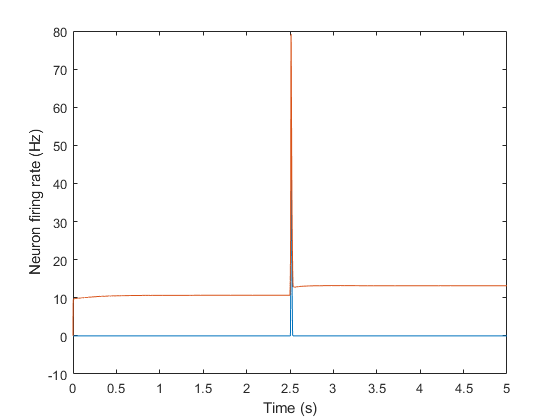

% Plot some results

%% Activity of a few individual excitory neurons

E_1 = results(:,1); % all rows, first column are the results for E_1
plot(t,E_1)
xlabel('Time (s)')
ylabel('Neuron firing rate (Hz)')
hold on

E_last = results(:,N_E); % all rows, N_Eth column are the results for last excitory neuron
plot(t,E_last)
xlabel('Time (s)')
ylabel('Neuron firing rate (Hz)')
hold off

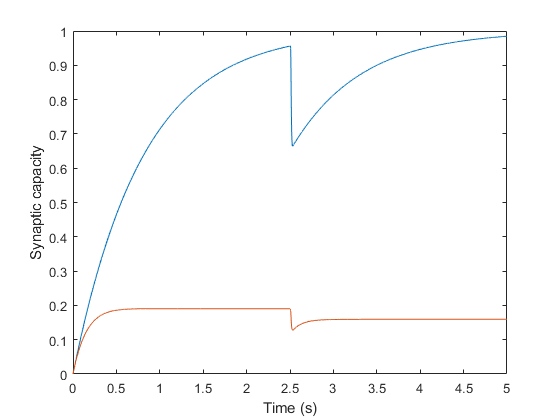


%% Capacity of those neurons

x_1 = results(:,N_E+1);
plot(t,x_1)
xlabel('Time (s)')
ylabel('Synaptic capacity')
hold on 

x_last = results(:,N_E+N_E);
plot(t,x_last)
xlabel('Time (s)')
ylabel('Synaptic capacity')
hold off %blue is different to orange because of background noise

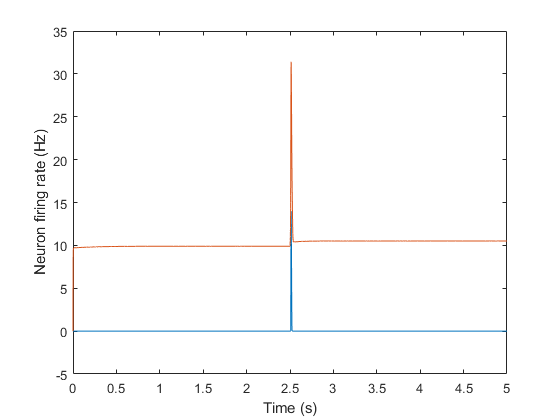


%% Activity of a few individual inhibitory neurons

I_1 = results(:,N_E+N_E+1);
plot(t,I_1)
xlabel('Time (s)')
ylabel('Neuron firing rate (Hz)')
hold on 
I_last = results(:,N_E+N_E+N_I);
plot(t,I_last)
xlabel('Time (s)')
ylabel('Neuron firing rate (Hz)')
hold off

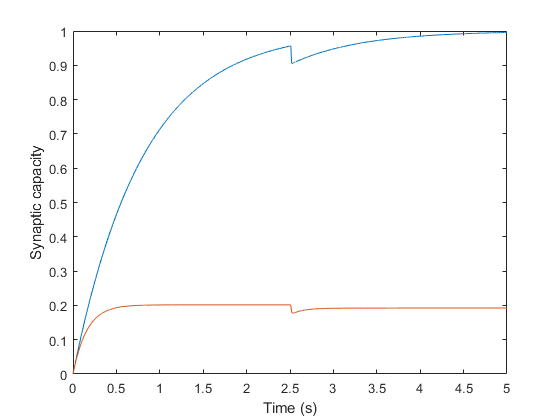


%% Capacity of those neurons

y_1 = results(:,N_E+N_E+N_I+1);
plot(t,y_1)
xlabel('Time (s)')
ylabel('Synaptic capacity')
hold on 
y_last = results(:,end);
plot(t,y_last)
xlabel('Time (s)')
ylabel('Synaptic capacity')
hold off

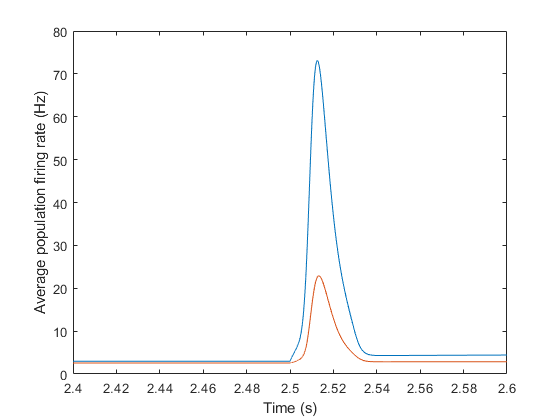

% Full excitory population average

E_total = mean(results(:,1:N_E),2); % all rows, first column are the results for E_1
plot(t,E_total)
xlim([2.4 2.6])
xlabel('Time (s)')
ylabel('Average population firing rate (Hz)')
% Full excitory population average
hold on
I_total = mean(results(:,N_E+N_E+1:N_E+N_E+N_I),2); % all rows, first column are the results for E_1
plot(t,I_total)
hold off

%xlabel('Time (s)')
%ylabel('Average population firing rate (Hz)')

function dvariablesdt = columndynamics(t, variables, params, inputs, sensory_input, sensory_input_time)

    % unpack parameters

    N_E = params(1);
    N_I = params(2);
    tau_E = params(3);
    tau_I = params(4);
    tau_ref_E = params(5);
    tau_ref_I = params(6);
    tau_rec = params(7);
    U = params(8);
    J_0_EE = params(9);
    J_0_EI = params(10);
    J_0_IE = params(11);
    J_0_II = params(12);

    % unpack inputs
    
    e_E = inputs(1:N_E);
    e_I = inputs((N_E+1):(N_E+N_I));
    if (t > sensory_input_time)
        s = sensory_input;  % each neuron has same sensory input after the time specified
    else
        s = 0;
    end

    % unpack variables (the state space)
    
    E = variables(1:N_E).';
    x = variables((N_E+1):(N_E+N_E)).';
    I = variables((N_E+N_E+1):(N_E+N_E+N_I)).';
    y = variables((N_E+N_E+N_I+1):end).';
    
    % precalculations
    
    w_E = J_0_EE*(sum(U*x.*E)/N_E) + J_0_EI*(sum(U*y.*I)/N_I); % weighted sum of excitory inputs (scalar)
    w_I = J_0_IE*(sum(E)/N_E) + J_0_II*(sum(I)/N_I); % weighted sum of inhibitory inputs (scalar)
    z_E =  w_E + e_E + s; % add the background input and sensory input vectors to the scalar (vector result)
    z_I =  w_I + e_I; % add the background input to the scalar (vector result)

    % calculate the derivatives

    E_dot = (-E + (1-tau_ref_E*E).*max(0, z_E))/tau_E;
    I_dot = (-I + (1-tau_ref_I*I).*max(0, z_I))/tau_I;
    x_dot = (1-x)/tau_rec - U*(x.*E);
    y_dot = (1-y)/tau_rec - U*(y.*I);

    % repack the results
    
    dvariablesdt_row = [E_dot, x_dot, I_dot, y_dot];
    dvariablesdt = dvariablesdt_row(:); % results need to be in a column
    
end